atom = Alkali("Lithium7");
laser = GaussianBeam( ...
    wavelength = 1064e-9,...
    direction = [0;1;0],...
    polarization = [0;0;1],...
    power = 1, ...
    waist = 110e-6 ...
    );
ol = OpticalLattice(atom,laser);
kL = laser.AngularWavenumber;
lambda = laser.Wavelength;
a = lambda / 2;
Er = ol.RecoilEnergy;
ol.DepthKd = 8.8458 * Er;

nq = 20000;
na = 2;
qmin = - kL;
qmax =  kL;
qList = linspace(qmin,qmax,nq);
% qList = qList(1:end-1);
% nq = nq - 1;
xRange = na*a;
nx = na * 1000;
xList = linspace(-xRange / 2,xRange / 2,nx);

maxband = 4;
ol.computeAll1D(qList,maxband,xList)

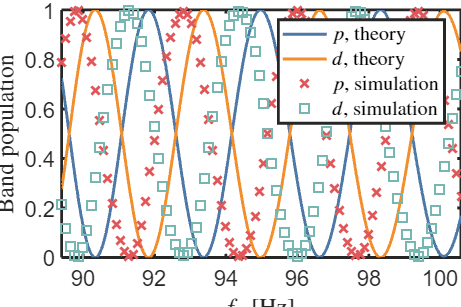

bList = num2cell(linspace(1.2e-2,1.35e-2,96));
niB = 543.6e-4; %non-interacting feshbach field
bField = cellfun(@(x) MagneticField(...
    bias = [0;0;niB],...
    gradient = [0,0,0;0,0,0;0,x,0]),bList,'UniformOutput',false);
M = atom.mass;
load simData.mat

mp = MagneticPotential(atom,bField{1});
stateIdx = mp.StateIndex;
stateList = atom.(mp.Manifold).StateList;
mJ = stateList.MJ(stateIdx);
gJ = stateList.gJ(stateIdx);
mI = stateList.MI(stateIdx);
gI = stateList.gI(stateIdx);
muB = Constants.SI("muB");
h = Constants.SI("hbar") * 2 * pi;
hbar = Constants.SI("hbar");
prefactor = (mJ * gJ + mI * gI) * muB / h;
FList0 = abs(h * prefactor * cell2mat(bList));
omegaBList0 = FList0 * a / hbar;
aList = abs(FList0 / M);


g = 9.81;
hbar = Constants.SI("hbar");
h = hbar * 2 * pi;
F0 = M * g;
NF = 1000;
FList = linspace(FList0(1),FList0(end),NF);
omegaBList = FList * a / hbar;
% qR = 0.80 * kL;
qR = 0.802491 * kL;
V0 = h * ol.DepthKd;
A = ol.ModCouplingList;
Apd = squeeze(A(2,3,:));
[~,qRIdx] = min(abs(qList-qR));
[~,qRIdx2] = min(abs(qList+qR));
omegaDrive = 143.2231e3 * 2 * pi;


E = h * ol.BandEnergyList;
Ed = E(3,:);
Ep = E(2,:);
dq = qList(2) - qList(1);
dEdq = gradient(Ed-Ep,dq);
alphaList = 1 / (V0) / abs(Apd(qRIdx)) .*...
    sqrt(log(4)/pi.*FList.*abs(dEdq(qRIdx)));

tList = (FList ./ hbar^2 * abs(dEdq(qRIdx))).^(-1/2);

vList = FList ./ hbar^2 * abs(dEdq(qRIdx));
alpha = 0.035;
Omega = alpha * V0 * abs(Apd(qRIdx)) / hbar;
deltaList = Omega^2 / 4 ./ vList;
PList = exp(-2*pi*deltaList);

gammaarg = sym(1-1i*deltaList);
gammaList = double(gamma(gammaarg));
phiS = pi/4 + deltaList .* (log(deltaList) - 1) + angle(gammaList);


% qR = qR + 0.001485 * kL;
% dq = 0.0047 * kL;
% qR = 0.8025 * kL;
[~,qRIdx] = min(abs(qList-qR));
[~,qRIdx2] = min(abs(qList+qR));
dE = Ed - Ep;
dE = dE - omegaDrive * hbar;
phiD = trapz(qList(qRIdx:end),dE(qRIdx:end)) + trapz(qList(1:qRIdx2),dE(1:qRIdx2));
phiD = phiD ./ FList;
% phiD = sum(dE(qRIdx:end)) + sum(dE(1:qRIdx2));
% phiD = phiD * dq ./ FList;
% phiD = phiD * 1.011;

pop = 4*PList .* (1-PList) .* (sin(phiD/2 + phiS + pi/2)).^2;

close(figure(1))
fig = figure(1);
plot(FList / F0,alphaList);
xlabel("$F / Mg$",'Interpreter','latex')
ylabel("$\alpha_{\mathrm{LZBS}}$",'Interpreter','latex')
axis([-inf,inf,-inf,inf])
render
savePDF(fig,'alpha')

close(figure(1))
fig = figure(1);
plot(FList / F0,tList * 1e6);
xlabel("$F / Mg$",'Interpreter','latex')
ylabel("Upper bound of $t_{\mathrm{LZBS}}~[\mu \mathrm{s}]$",'Interpreter','latex')
axis([-inf,inf,-inf,inf])
render
savePDF(fig,'t')

close(figure(1))
fig = figure(1);
plot(omegaBList / 2 / pi,1 - pop,omegaBList / 2 / pi,pop,...
    omegaBList0 / 2 / pi,bandPop(:,2),'+',omegaBList0 / 2 / pi,bandPop(:,3),'.');
xlabel("$f_{\mathrm{B}}$ [Hz]",'Interpreter','latex')
ylabel("Band population",'Interpreter','latex')
axis([-inf,inf,0,1])
legend("$p$, theory","$d$, theory","$p$, simulation","$d$, simulation",'Interpreter','latex')
render

% savePDF(fig,'pop')


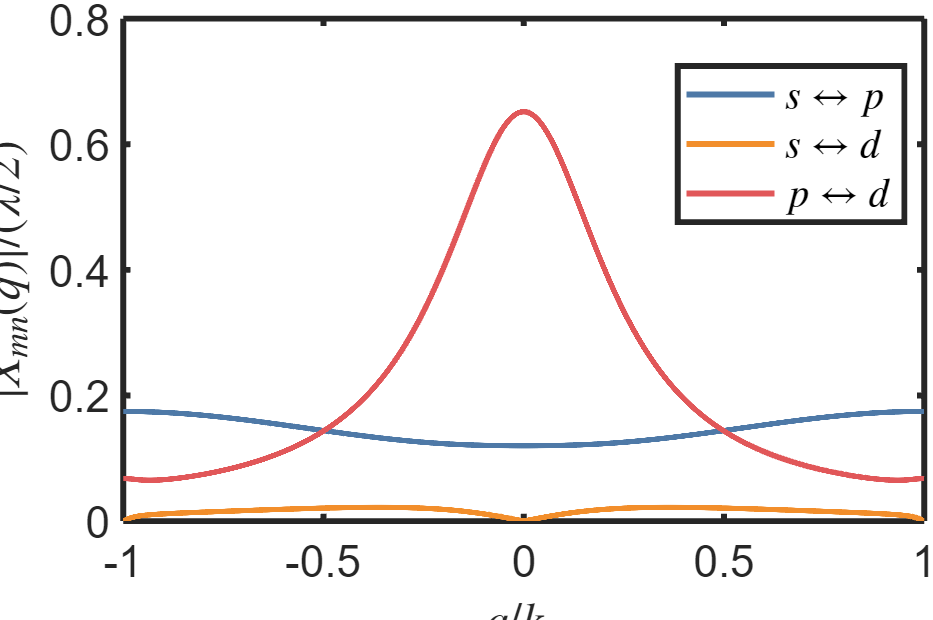

X = ol.BoCouplingList;
close(figure(1))
fig = figure(1);
idx = 1:800;
plot(qList/kL,abs(squeeze(X(1,2,:))) ./ a , qList/kL,abs(squeeze(X(1,3,:))) ./ a , qList/kL,abs(squeeze(X(2,3,:))) ./ a);
xlabel("$q/k_{\mathrm{L}}$",'Interpreter','latex')
ylabel("$|X_{mn}(q)| / (\lambda / 2)$",'Interpreter','latex')
legend("$s\leftrightarrow p$","$s\leftrightarrow d$","$p\leftrightarrow d$",'Interpreter','latex')
render

% savePDF(fig,'X')

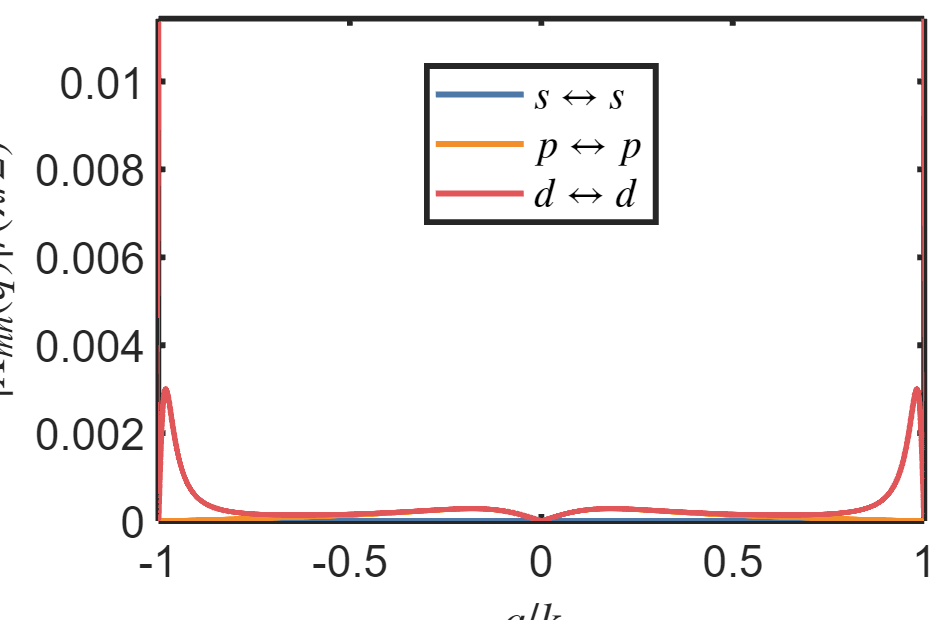

X = ol.BoCouplingList;
close(figure(1))
fig = figure(1);
idx = 1:800;
plot(qList/kL,abs(squeeze(X(1,1,:))) ./ a , qList/kL,abs(squeeze(X(2,2,:))) ./ a , qList/kL,abs(squeeze(X(3,3,:))) ./ a);
xlabel("$q/k_{\mathrm{L}}$",'Interpreter','latex')
ylabel("$|X_{mn}(q)| / (\lambda / 2)$",'Interpreter','latex')
legend("$s\leftrightarrow s$","$p\leftrightarrow p$","$d\leftrightarrow d$",'Interpreter','latex')
render

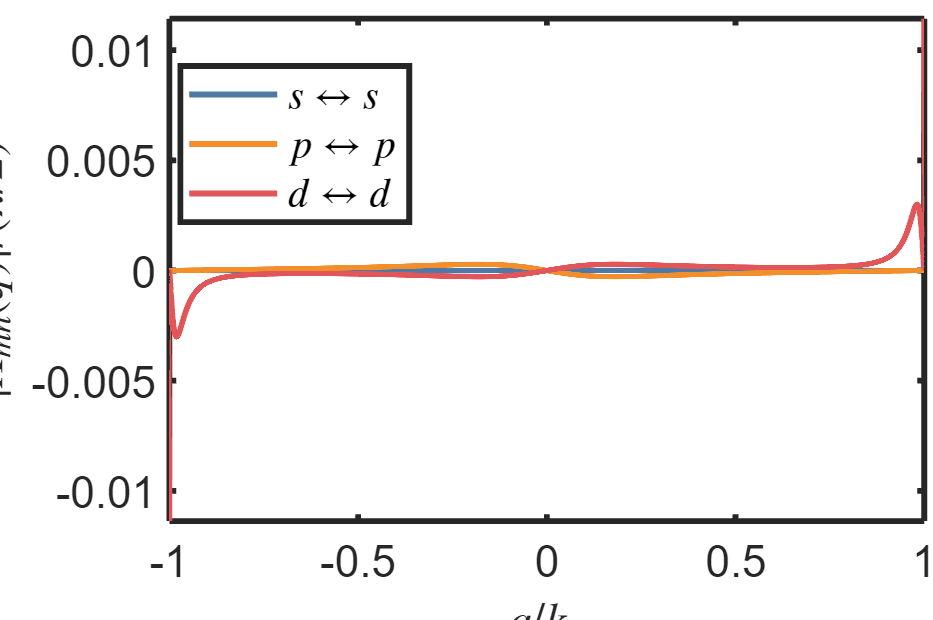

X = ol.BoCouplingList;
close(figure(1))
fig = figure(1);
idx = 1:800;
plot(qList/kL,imag(squeeze(X(1,1,:))) ./ a , qList/kL,imag(squeeze(X(2,2,:))) ./ a , qList/kL,imag(squeeze(X(3,3,:))) ./ a);
xlabel("$q/k_{\mathrm{L}}$",'Interpreter','latex')
ylabel("$|X_{mn}(q)| / (\lambda / 2)$",'Interpreter','latex')
legend("$s\leftrightarrow s$","$p\leftrightarrow p$","$d\leftrightarrow d$",'Interpreter','latex')
render

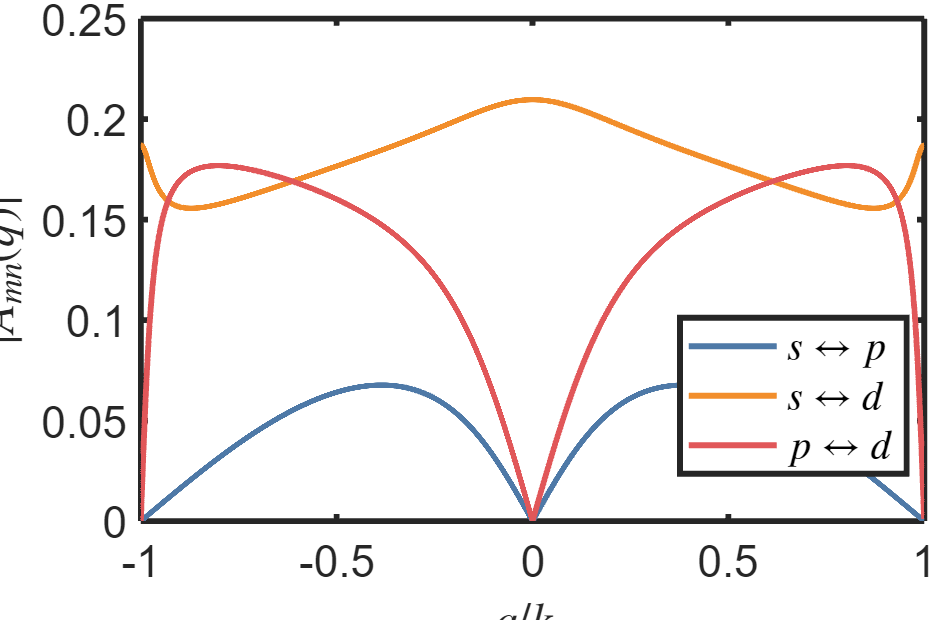

A = ol.ModCouplingList;
close(figure(1))
fig = figure(1);
ax = gca;
plot(ax,qList/kL,abs(squeeze(A(1,2,:))),qList/kL,abs(squeeze(A(1,3,:))),qList/kL,abs(squeeze(A(2,3,:))));
xlabel("$q/k_{\mathrm{L}}$",'Interpreter','latex')
ylabel("$|A_{mn}(q)|$",'Interpreter','latex')
legend("$s\leftrightarrow p$","$s\leftrightarrow d$","$p\leftrightarrow d$",'Interpreter','latex')
render

% savePDF(fig,'A')

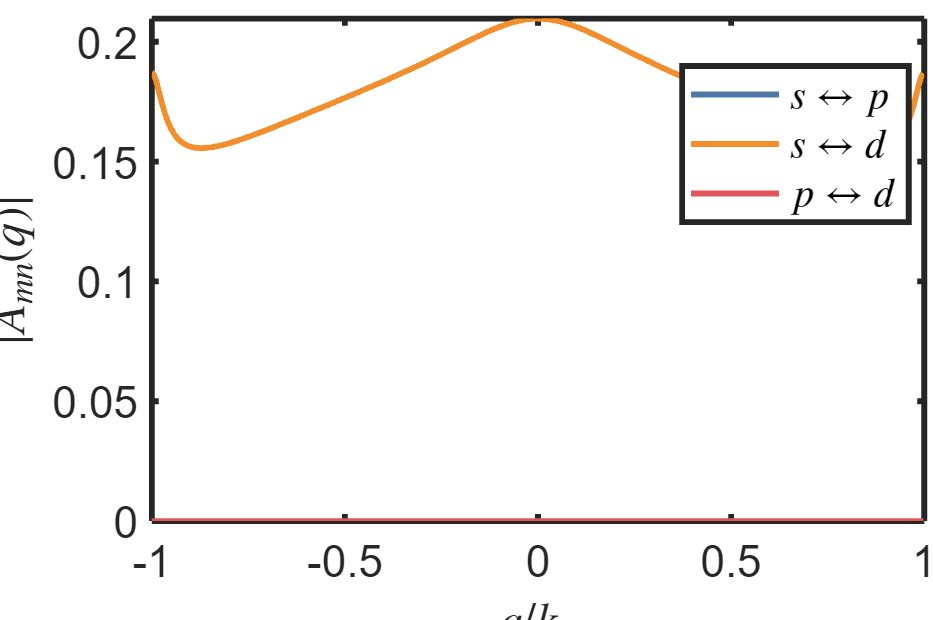

A = ol.ModCouplingList;
close(figure(1))
fig = figure(1);
ax = gca;
plot(ax,qList/kL,real(squeeze(A(1,2,:))),qList/kL,real(squeeze(A(1,3,:))),qList/kL,real(squeeze(A(2,3,:))));
xlabel("$q/k_{\mathrm{L}}$",'Interpreter','latex')
ylabel("$|A_{mn}(q)|$",'Interpreter','latex')
legend("$s\leftrightarrow p$","$s\leftrightarrow d$","$p\leftrightarrow d$",'Interpreter','latex')
render

% savePDF(fig,'A_angle')

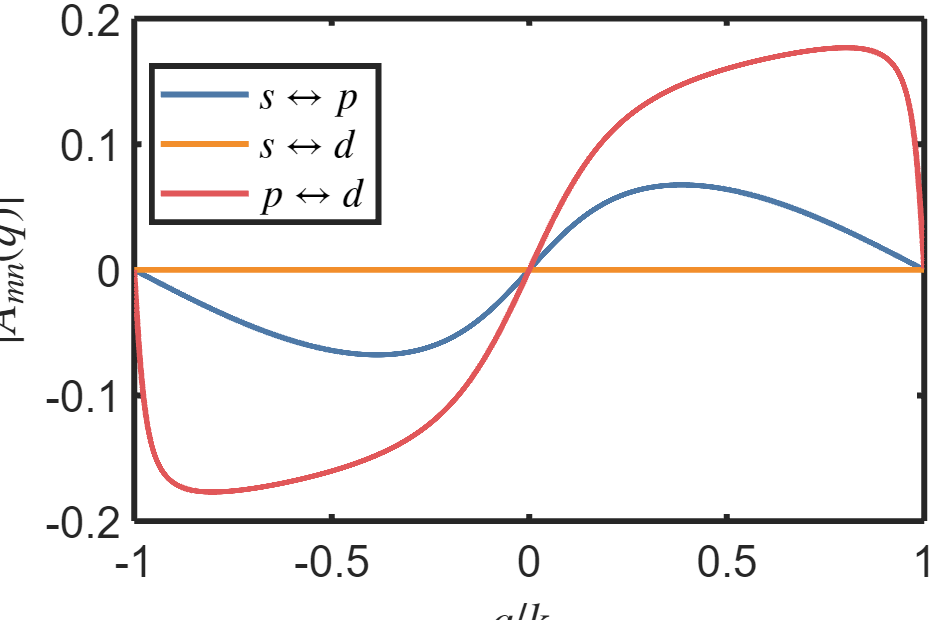

A = ol.ModCouplingList;
close(figure(1))
fig = figure(1);
ax = gca;
plot(ax,qList/kL,imag(squeeze(A(1,2,:))),qList/kL,imag(squeeze(A(1,3,:))),qList/kL,imag(squeeze(A(2,3,:))));
xlabel("$q/k_{\mathrm{L}}$",'Interpreter','latex')
ylabel("$|A_{mn}(q)|$",'Interpreter','latex')
legend("$s\leftrightarrow p$","$s\leftrightarrow d$","$p\leftrightarrow d$",'Interpreter','latex')
render